**Problem 3**

**3(a) Create AR(1) Function**

%function[y] = AR1( phi0, phi1, sig2eps, T, y0)
%epsilon = normrnd(0, sig2eps,1, T);   generate epsilon
%y(1) = y0                 assign y(1) = 0 (theoritical unconditional mean)
%   for t=2:T
%        y(t)=phi0+phi1*y(t-1)+epsilon(t);
%   end
%end


**3(b) Simulate AR(1) process**

AR = AR1(0,0.8,1,250,0)    %input given parameters

y = 0

AR =          0   -0.4998   -1.7251   -0.9128   -0.1498    0.4255   -0.4137    0.5817    0.8676    1.7719    2.6308    1.6805    1.1616   -0.8300   -0.0485   -0.5714   -1.0000   -1.6167   -1.3185    0.3451   -0.2044   -0.4495    0.1189    0.7965    1.2600    1.2107    0.9684   -0.3979    0.5863    1.6518    1.1751    0.8104    0.2917    1.1647    2.0646    2.4079    2.4870    3.1724    1.3348    1.3115    0.2618    1.8282    1.0138    1.7836    0.4511    1.0266    1.8426    0.9048    0.4791   -0.2683


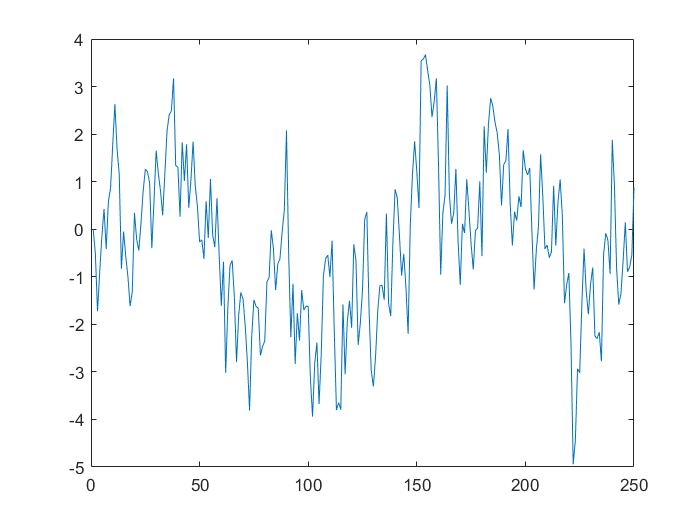

plot(AR);

**3(c) Comparing theoritical autocorrelations with the ones from simulation**

For theoritical autocorrelation

phi1 = 0.8

phi1 = 0.8000

for t=1:19
    ARth(t) = phi1^(t);
end

Plotting the two

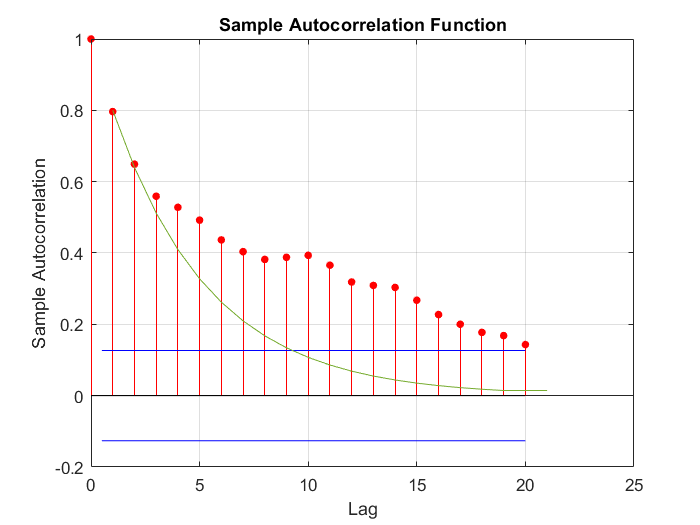

autocorr(AR)
hold on
plot(ARth)

**Note: **The green line represents theoritical autocorrelations.

The red dot represents autocorrelations from simulation.